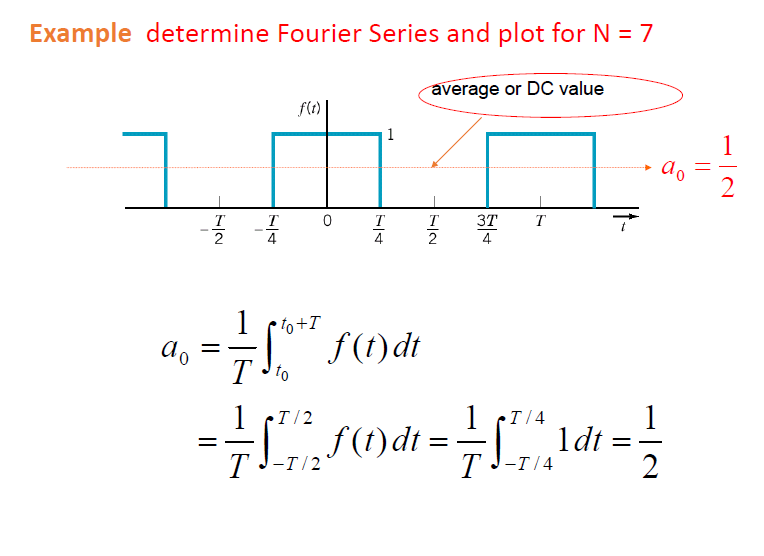

clear
clf
clc

Ts=0.01;
T=5;
syms t y 

%t=-T/2:Ts:T/2-Ts

f1=0;
f2=1;
f3=0;


N=7;%number of harmonic 
n=1:N;

a0=(1/T)*(int(f1,t,-T/2,-T/4)+int(f2,t,-T/4,T/4)+int(f3,t,T/4,T/2))

$$a0 = \frac{1}{2}$$

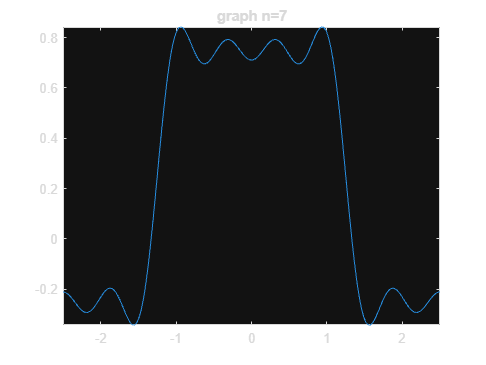

a_n=(2/T)*(int(f1*cos(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*cos(2*pi*n*t/T),t,-T/4,T/4)+int(f3*cos(2*pi*n*t/T),t,T/4,T/2));
b_n=(2/T)*(int(f1*sin(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*sin(2*pi*n*t/T),t,-T/4,T/4)+int(f3*sin(2*pi*n*t/T),t,T/4,T/2));

F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    fplot(F,[-T/2, T/2])
    title('graph n=7')
end


%************************
fprintf("n=[1,7]")

n=[1,7]

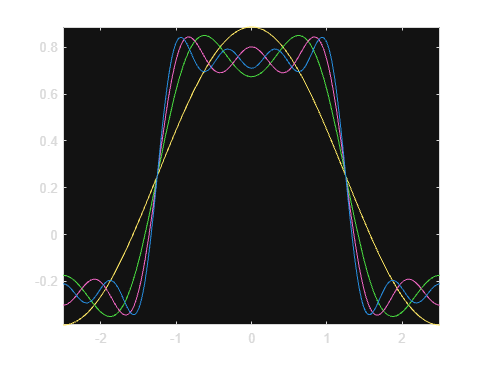

fplot(F,[-T/2, T/2])
F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    
    hold on
    fplot(F,[-T/2, T/2])
    hold off
    
end

%*************************
F

$$F = \frac{2\,\cos\left(2\,\pi \,t\right)}{5\,\pi }+\frac{2\,\cos\left(\frac{2\,\pi \,t}{5}\right)}{\pi }-\frac{2\,\cos\left(\frac{6\,\pi \,t}{5}\right)}{3\,\pi }-\frac{2\,\cos\left(\frac{14\,\pi \,t}{5}\right)}{7\,\pi }+\frac{1}{4}$$